# Luria-Delbrück experiment

As explained in the document with the experiment background [Luria](https://en.wikipedia.org/wiki/Salvador_Luria) and [Delbrück](https://en.wikipedia.org/wiki/Max_Delbr%C3%BCck) wanted to discern between two standing theories of inheritance:

- Post–adaptive mutations (aquired immunity hypothesis)

- Pre–adaptive mutations (inherited mutations hypothesis)

In this document we numerically simulate both hypothesis in order to get a feeling of what to expect from both scenarios in our experiments. But in order to simulate these hypothesis we must recall the possible outcomes of each scenario as depicted in the following figure

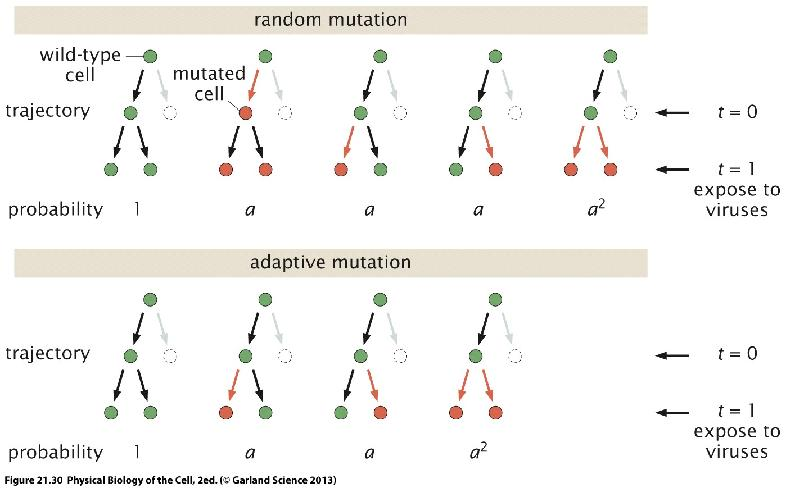

## Aquired immunity hypothesis

As shown in the figure there are four different outcomes for the adaptive mutation hypothesis. What this scenario assumes is that given a fixed number of cells plated on selective media are in some fashion "**induced**" to undergo mutations allowing survival given a probability $a$ of mutating.

Our objective is then, given a fixed number of cells, to "**toss the coin**" for each cell in order to decide if they will acquire the mutation and survive or not.

Let's first initialize the variables that we will need

% probability that a particular cell will acquire the mutation
mut_rate = 1e-5;
% number of cells in the simulation
n_cells = 128000;

 Now lets determine the number of simulations to run and initialize the array to save our results

% number of simulations
n_simulations = 1000;
% initialize array to save outcomes
outcomes = zeros(n_simulations, 1);

Time to run the simulation! For this we will generate random numbers between 0 and 1 using the function **rand**. Since these numbers are generated using a [uniform distribution](https://en.wikipedia.org/wiki/Uniform_distribution_(continuous)), i.e. each number has equal probability of occurring, the numbers that are less than or equal to our mutation rate add up to this probability. If you are not sure about this claim try to integrate the PDF of this distribution from zero to an unknown variable $x$ such that the integral is equal to the mutation rate.

% run the simulation!
for i=1:n_simulations
    outcomes(i) = sum(rand(n_cells, 1) < mut_rate);
end

Let's now plot the histogram of the results to visualize the expected distribution

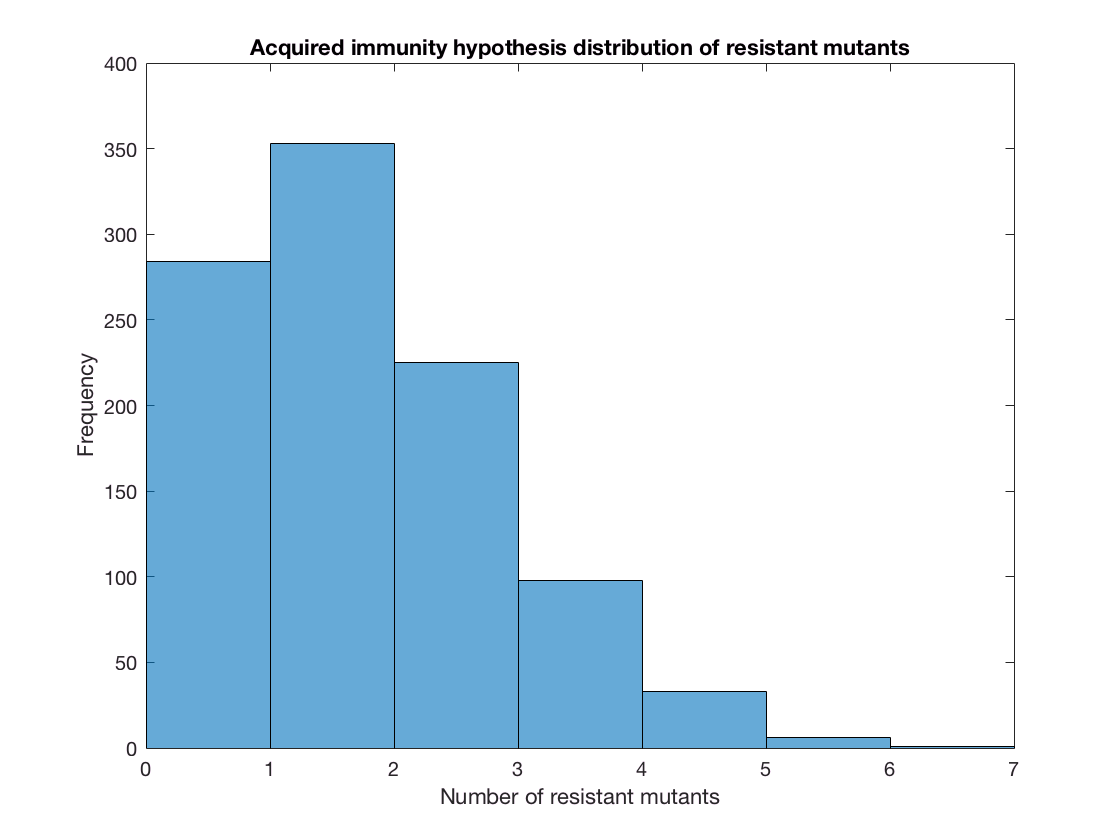

% plot the histogram with bins of size 1
histogram(outcomes, 0:1:max(outcomes))
xlabel('Number of resistant mutants')
ylabel('Frequency')
title('Acquired immunity hypothesis distribution of resistant mutants')

% print relevant quantities
disp(['Mean number of mutants: ' num2str(mean(outcomes))]);

Mean number of mutants: 1.266


disp(['Variance in number of mutants: ' num2str(var(outcomes))])

Variance in number of mutants: 1.2605


disp(['Fano factor: ' num2str(var(outcomes) / mean(outcomes))])

Fano factor: 0.99566


## Inherited mutation hypothesis

The alternative scenario assumes that mutations occur at random with which the natural variability of the population increases over time. Once a selection on the environment appears only the cells with the right mutations will survive. In order to simulate this scenario we have written a function for you to use. The function **inherited_mut** takes 3 arguments: 

- mutation rate

- initial number of cells

- number of cell divisions to run the simulation

Let's set these three parameters

% mutation rate calibrated to give ≈ 1 mutant per plate.
mut_rate_inherit = 3e-6;
% initial number of cells
n_0 = 1000;
% number of cell divisions
n_divisions = 7;
% note that 128000 = 1000 * 2^7 if you were wondering why we chose that number

Now that we have these parameters let's run the function 1000 times to plot the histogram of resistant cells

n_simulations = 1000;
outcomes_inherit = zeros(n_simulations, 1);
for i=1:n_simulations
    outcomes_inherit(i) = inherited_mut(mut_rate_inherit, n_0, n_divisions);
end

Now let's plot the results as before

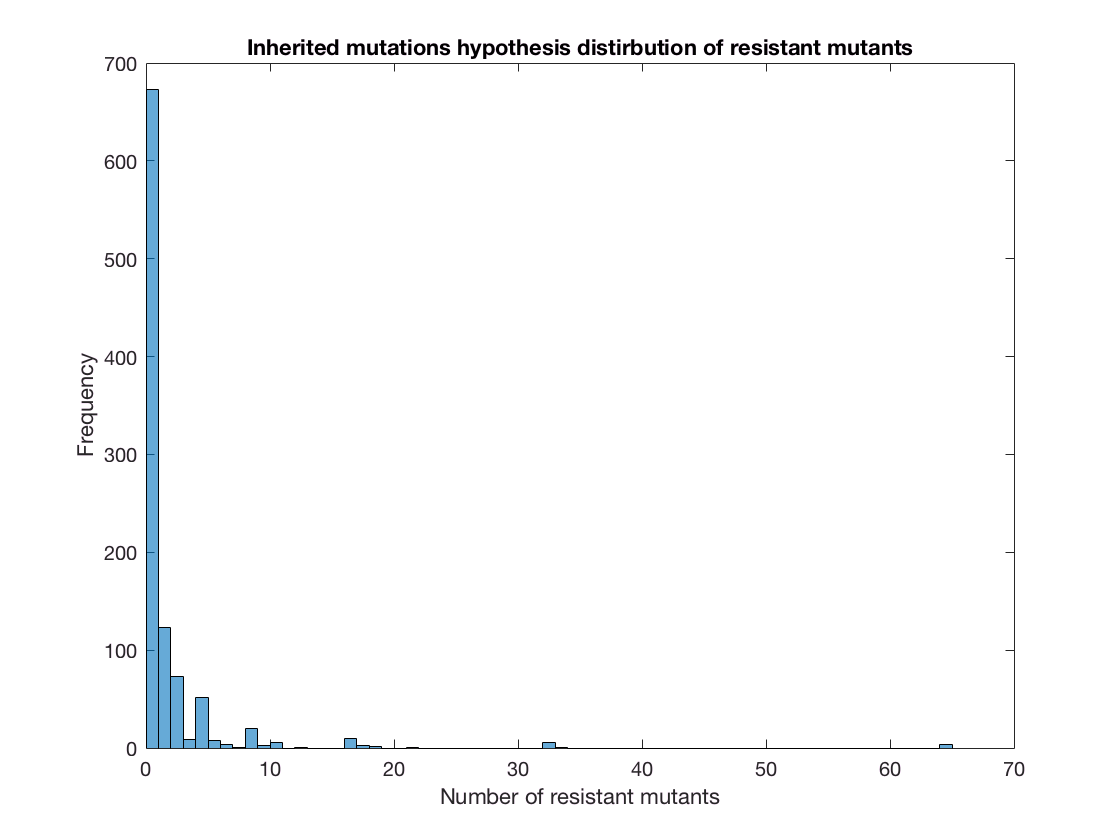

histogram(outcomes_inherit, 0:1:max(outcomes_inherit))
xlabel('Number of resistant mutants')
ylabel('Frequency')
title('Inherited mutations hypothesis distirbution of resistant mutants')

% print relevant quantities
display(['Mean number of mutants: ' num2str(mean(outcomes_inherit))])

Mean number of mutants: 1.584


display(['Variance in number of mutants: ' num2str(var(outcomes_inherit))])

Variance in number of mutants: 29.7707


display(['Fano factor: ' num2str(var(outcomes_inherit) / mean(outcomes_inherit))])

Fano factor: 18.7946


Wow! There are definitely significant differences between the expected distirbutions given both hypothesis. This was the beauty of Luria and Delbruck's insight . Quantitative predictions testable with a clever experiment allow them to distinguish between proposed inheritance mechanisms!